# Compare airspeedspeed

## Load Birdscan

load('BS/Sempach_2018_cleaned')
BS.airspeed=BS.groundspeed-BS.windspeed;
BS.p_bird = BS.p_unidbird+BS.p_passer+BS.p_wader+BS.p_lsb;
BS = removevars(BS,{'p_unidbird','p_passer','p_unidbird','p_wader','p_lsb'});
BS(isnan(BS.groundspeed),:)=[];
BS.s=2*BS.height.*tand(BS.theta/2);
BS.tau=BS.s./abs(BS.groundspeed);

add value of BS location.

lat = 47.128054;
lon = 8.192377;
alt = 540;

Add seasonal variables

t=datetime('2018-01-01'):datetime('2019-01-01');
season = datetime([737121 737184 737273 737384 737121+365],'ConvertFrom','datenum');
season_label = {'Spring (02-Mar  - 04-May)','Summer (4-May - 1-Aug)','Autumn (1-Aug - 20-Nov)','Winter (20-Nov - 02-Mar)'};
BS.season = sum(bsxfun(@gt, datenum(BS.time_string), datenum(season)),2);

Add day assocaite

[~,BS.day_id] = ismember(dateshift(BS.time_string,'start','day'),t);

Define parameter of histogram

norm = 'pdf';
edge_angle = 16;
edge_hist = 0:30;

## Filter BS data

Define the thresholds of the filters

minprobinsect=.7;
minprobbird=.7;
maxalt_insect = 1500;%1000-alt;
maxalt_bird = 1500;%1400-alt;
minalt = 600-alt;
minalpha = 0;%180-60;
maxalpha = 360;%180+60;
% maxtheta = 17*2;
% maxdist = 500; % maximum distance while in the beam
mintau = 2;
maxtau = 60;%30; % Max duration in beam in sec

Apply filter

BSs = BS( BS.height>minalt ...
            & ( (BS.height<maxalt_bird & BS.isBird) | (BS.height<maxalt_insect & ~BS.isBird) ) ...
            & (BS.p_insect>minprobinsect|BS.isBird) ...
            & (BS.p_bird >minprobbird|~BS.isBird) ...
            & (BS.alpha > minalpha & BS.alpha < maxalpha) ...
            ...% & (BS.theta < maxtheta) ...
            & BS.tau < maxtau & BS.tau > mintau...
            & ~isnan(BS.groundspeed),:);

Description of the data before and after filtering

fprintf(['Number of insect track: ' num2str(sum(~BS.isBird)) ' (nan: ' num2str(mean(isnan(BS.groundspeed(~BS.isBird)))*100,2) 'perc.) \nNumber of bird track: ' num2str(sum(BS.isBird)) ' (nan: ' num2str(mean(isnan(BS.groundspeed(BS.isBird)))*100,2) 'perc)'])

Number of insect track: 239130 (nan: 0perc.) 
Number of bird track: 95311 (nan: 0perc)

disp(['Filter kept ' num2str(round(size(BSs,1)/size(BS,1)*100)) '% of the data'])

Filter kept 91% of the data


fprintf(['Number of insect track: ' num2str(sum(~BSs.isBird)) ' \nNumber of bird track: ' num2str(sum(BSs.isBird)) ])

Number of insect track: 215637 
Number of bird track: 88561

Illustration: Probability

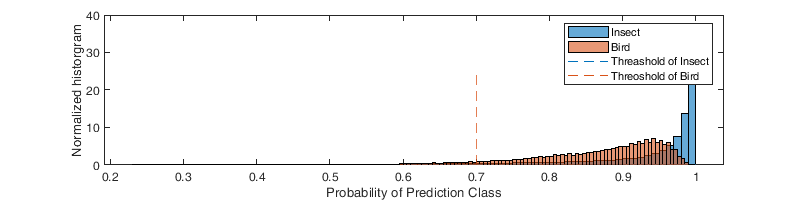

figure('position',[0 0 800 200]); hold on;
col = get(gca,'ColorOrder');
p1=histogram(BS.p_insect(~BS.isBird),'Normalization',norm);
p2=histogram(BS.p_bird(BS.isBird),'Normalization',norm);
plot([minprobinsect minprobinsect],[0 25],'--','Color',col(1,:))
plot([minprobbird minprobbird],[0 25],'--','Color',col(2,:));
xlabel('Probability of Prediction Class'); ylabel('Normalized historgram'); box on;
legend({'Insect','Bird','Threashold of Insect','Threoshold of Bird'})

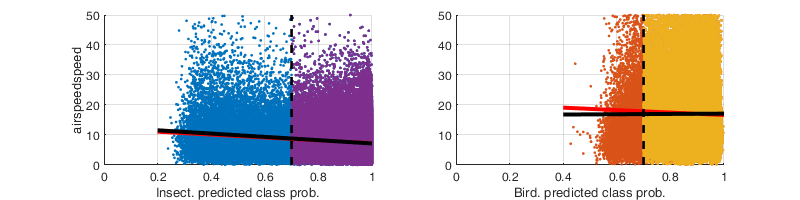

figure('position',[0 0 800 200]);
subplot(1,2,1); hold on; 
plot(BS.p_insect(~BS.isBird),abs(BS.airspeed(~BS.isBird)),'.');
plot(BSs.p_insect(~BSs.isBird),abs(BSs.airspeed(~BSs.isBird)),'.','Color',col(4,:));
h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
plot([minprobinsect minprobinsect],[0 50],'--k','LineWidth',2)
axis([0 1 0 50 ]); grid on; ylabel('airspeedspeed'); xlabel('Insect. predicted class prob.')
subplot(1,2,2); hold on;
set(gca,'ColorOrderIndex',2)
plot(BS.p_bird(BS.isBird),abs(BS.airspeed(BS.isBird)),'.','Color',col(2,:));
plot(BSs.p_bird(BSs.isBird),abs(BSs.airspeed(BSs.isBird)),'.','Color',col(3,:));
h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
plot([minprobbird minprobbird],[0 50],'--k','LineWidth',2);
axis([0 1 0 50 ]); grid on;  xlabel('Bird. predicted class prob.')

Illustration Altitude

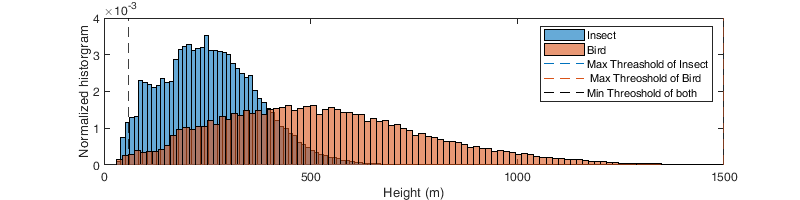

figure('position',[0 0 800 200]); hold on;
col = get(gca,'ColorOrder');
p1=histogram(BS.height(~BS.isBird),200,'Normalization',norm);
p2=histogram(BS.height(BS.isBird),200,'Normalization',norm);
plot([maxalt_insect maxalt_insect],[0 .004],'--','Color',col(1,:))
plot([maxalt_bird maxalt_bird],[0 .004],'--','Color',col(2,:));
plot([minalt minalt],[0 .004],'--','Color','k')
xlabel('Height (m)'); ylabel('Normalized historgram'); box on;
legend({'Insect','Bird','Max Threashold of Insect',' Max Threoshold of Bird' ,'Min Threoshold of both'})
xlim([0 1500])

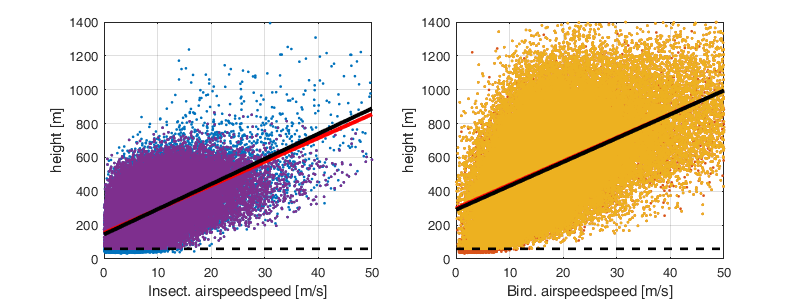

figure('position',[0 0 800 300]); hold on; 
subplot(1,2,1); hold on;
plot(abs(BS.airspeed(~BS.isBird)),BS.height(~BS.isBird),'.');
plot(abs(BSs.airspeed(~BSs.isBird)),BSs.height(~BSs.isBird),'.','Color',col(4,:));
h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
axis([0 50 0 1400]); xlabel('Insect. airspeedspeed [m/s]'); ylabel('height [m]'); box on; grid on;
plot([0 50],[minalt minalt],'--k','LineWidth',2);
plot([0 50],[maxalt_insect maxalt_insect],'--k','LineWidth',2);
subplot(1,2,2); hold on;
plot(abs(BS.airspeed(BS.isBird)),BS.height(BS.isBird),'.','Color',col(2,:));
plot(abs(BSs.airspeed(BSs.isBird)),BSs.height(BSs.isBird),'.','Color',col(3,:));
h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
plot([0 50],[minalt minalt],'--k','LineWidth',2);
plot([0 50],[maxalt_bird maxalt_bird],'--k','LineWidth',2);
axis([0 50 0 1400]); xlabel('Bird. airspeedspeed [m/s]'); ylabel('height [m]'); box on; grid on;

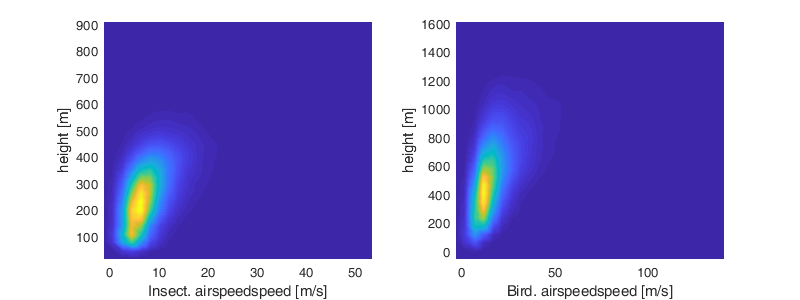

figure('position',[0 0 800 300]);
subplot(1,2,1); hold on;
ksdensity([abs(BSs.airspeed(~BSs.isBird)),BSs.height(~BSs.isBird)]); view(2); axis tight; shading interp 
xlabel('Insect. airspeedspeed [m/s]'); ylabel('height [m]')
subplot(1,2,2); hold on;
ksdensity([abs(BSs.airspeed(BSs.isBird)),BSs.height(BSs.isBird)]); view(2); axis tight; shading interp 
xlabel('Bird. airspeedspeed [m/s]'); ylabel('height [m]')

Alpha

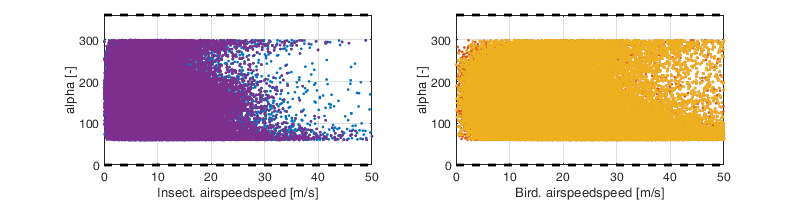

figure('position',[0 0 800 200]); hold on; 
subplot(1,2,1); hold on;
plot(abs(BS.airspeed(~BS.isBird)),BS.alpha(~BS.isBird),'.');
plot(abs(BSs.airspeed(~BSs.isBird)),BSs.alpha(~BSs.isBird),'.','Color',col(4,:));
% h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
axis tight; xlabel('Insect. airspeedspeed [m/s]'); ylabel('alpha [-]'); box on; grid on; xlim([0 50])
plot([0 50],[minalpha minalpha],'--k','LineWidth',2);
plot([0 50],[maxalpha maxalpha],'--k','LineWidth',2);
subplot(1,2,2); hold on;
plot(abs(BS.airspeed(BS.isBird)),BS.alpha(BS.isBird),'.','Color',col(2,:));
plot(abs(BSs.airspeed(BSs.isBird)),BSs.alpha(BSs.isBird),'.','Color',col(3,:));
%ksdensity([abs(BSs.airspeed(~BSs.isBird)),BSs.alpha(~BSs.isBird)]); view(2); axis tight; shading interp 
%h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
plot([0 50],[minalpha minalpha],'--k','LineWidth',2);
plot([0 50],[maxalpha maxalpha],'--k','LineWidth',2);
axis tight; xlabel('Bird. airspeedspeed [m/s]'); ylabel('alpha [-]'); box on; grid on; xlim([0 50])

Theta

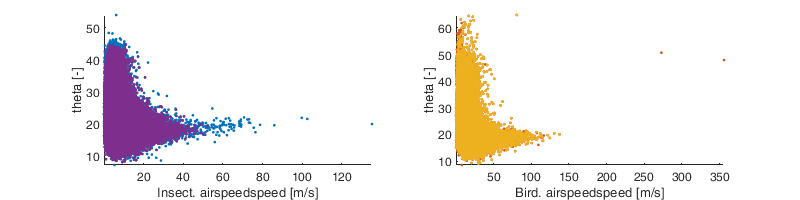

figure('position',[0 0 800 200]); hold on; 
subplot(1,2,1); hold on;
plot(abs(BS.airspeed(~BS.isBird)),BS.theta(~BS.isBird),'.');
plot(abs(BSs.airspeed(~BSs.isBird)),BSs.theta(~BSs.isBird),'.','Color',col(4,:));
% h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
axis tight; xlabel('Insect. airspeedspeed [m/s]'); ylabel('theta [-]')
%plot([0 50],[minalt minalt],'--k','LineWidth',2);
%plot([0 50],[maxalt_insect maxalt_insect],'--k','LineWidth',2);
subplot(1,2,2); hold on;
plot(abs(BS.airspeed(BS.isBird)),BS.theta(BS.isBird),'.','Color',col(2,:));
plot(abs(BSs.airspeed(BSs.isBird)),BSs.theta(BSs.isBird),'.','Color',col(3,:));
%h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
%plot([0 50],[minalt minalt],'--k','LineWidth',2);
%plot([0 50],[maxalt_bird maxalt_bird],'--k','LineWidth',2);
axis tight; xlabel('Bird. airspeedspeed [m/s]'); ylabel('theta [-]')

Distance in bream (s)

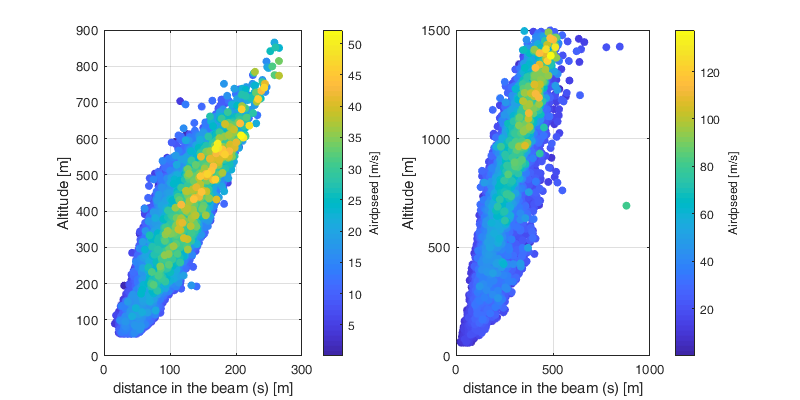

figure('position',[0 0 800 400]); hold on; 
subplot(1,2,1); hold on;
[~,tmp] = sort(BSs.airspeed); tmp(BSs.isBird(tmp))=[];
scatter(BSs.s(tmp),BSs.height(tmp),[], abs(BSs.airspeed(tmp)),'filled')
xlabel('distance in the beam (s) [m]'); ylabel('Altitude [m]'); c=colorbar;c.Label.String='Airdpseed [m/s]'; box on; grid on;
subplot(1,2,2); hold on;
[~,tmp] = sort(BSs.airspeed); tmp(~BSs.isBird(tmp))=[];
scatter(BSs.s(tmp),BSs.height(tmp),[], abs(BSs.airspeed(tmp)),'filled')
xlabel('distance in the beam (s) [m]'); ylabel('Altitude [m]'); c=colorbar;c.Label.String='Airdpseed [m/s]'; box on; grid on;

Duration in beam \tau

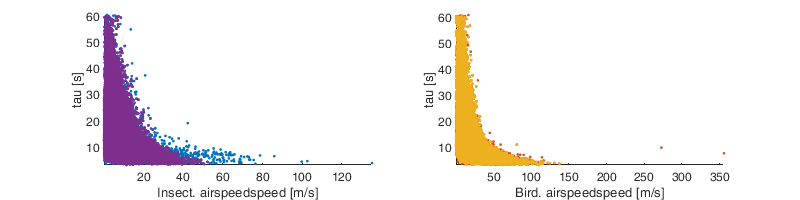

figure('position',[0 0 800 200]); hold on; 
subplot(1,2,1); hold on;
plot(abs(BS.airspeed(~BS.isBird)),BS.tau(~BS.isBird),'.');
plot(abs(BSs.airspeed(~BSs.isBird)),BSs.tau(~BSs.isBird),'.','Color',col(4,:));
% h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
axis tight; xlabel('Insect. airspeedspeed [m/s]'); ylabel('tau [s]')
%plot([0 50],[minalt minalt],'--k','LineWidth',2);
%plot([0 50],[maxalt_insect maxalt_insect],'--k','LineWidth',2);
subplot(1,2,2); hold on;
plot(abs(BS.airspeed(BS.isBird)),BS.tau(BS.isBird),'.','Color',col(2,:));
plot(abs(BSs.airspeed(BSs.isBird)),BSs.tau(BSs.isBird),'.','Color',col(3,:));
%h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
%plot([0 50],[minalt minalt],'--k','LineWidth',2);
%plot([0 50],[maxalt_bird maxalt_bird],'--k','LineWidth',2);
axis tight; xlabel('Bird. airspeedspeed [m/s]'); ylabel('tau [s]')

Distance in bream (s)

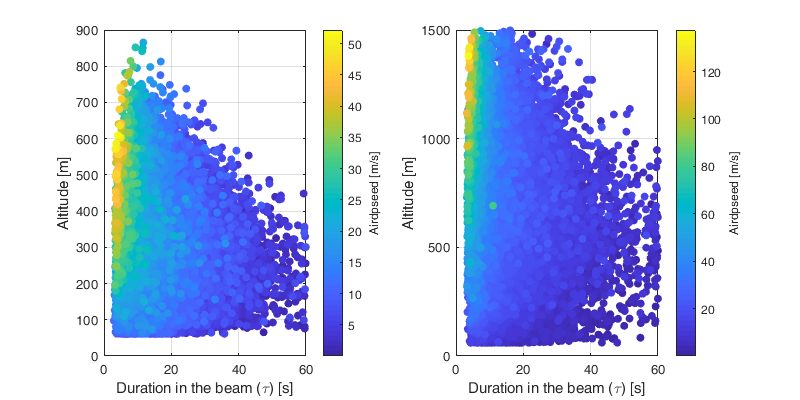

figure('position',[0 0 800 400]); hold on; 
subplot(1,2,1); hold on;
[~,tmp] = sort(BSs.airspeed); tmp(BSs.isBird(tmp))=[];
scatter(BSs.tau(tmp),BSs.height(tmp),[], abs(BSs.airspeed(tmp)),'filled')
xlabel('Duration in the beam (\tau) [s]'); ylabel('Altitude [m]'); c=colorbar;c.Label.String='Airdpseed [m/s]'; box on; grid on;
subplot(1,2,2); hold on;
[~,tmp] = sort(BSs.airspeed); tmp(~BSs.isBird(tmp))=[];
scatter(BSs.tau(tmp),BSs.height(tmp),[], abs(BSs.airspeed(tmp)),'filled')
xlabel('Duration in the beam (\tau) [s]'); ylabel('Altitude [m]'); c=colorbar;c.Label.String='Airdpseed [m/s]'; box on; grid on;

RCS

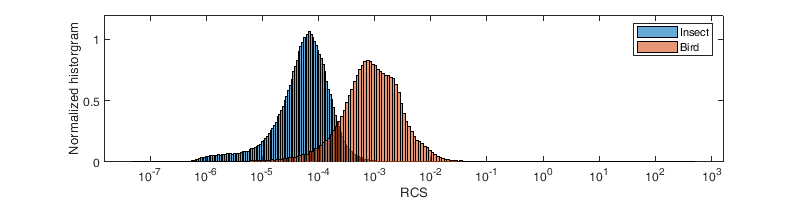

figure('position',[0 0 800 200]); hold on;
col = get(gca,'ColorOrder');
p1=histogram(log10(BS.rcs(~BS.isBird)),200,'Normalization',norm);
p2=histogram(log10(BS.rcs(BS.isBird)),200,'Normalization',norm);
xticklabels(cellfun(@(x) ['10^{' x '}'],xticklabels,'UniformOutput',false))
xlabel('RCS'); ylabel('Normalized historgram'); box on;
legend({'Insect','Bird'})

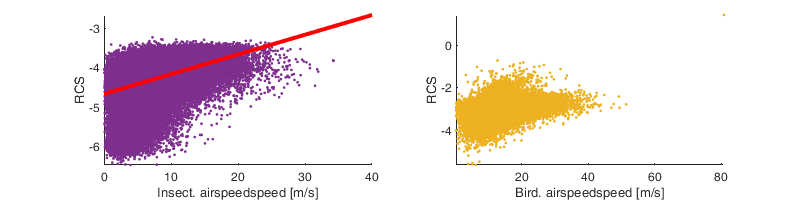

figure('position',[0 0 800 200]); hold on; 
subplot(1,2,1); hold on;
plot(abs(BSs.airspeed(~BSs.isBird)),log10(BSs.rcs(~BSs.isBird)),'.','Color',col(4,:));
h=lsline; h(1).LineWidth = 3; h(1).Color='r';
axis tight; xlabel('Insect. airspeedspeed [m/s]'); ylabel('RCS')
subplot(1,2,2); hold on;
plot(abs(BSs.airspeed(BSs.isBird)),log10(BSs.rcs(BSs.isBird)),'.','Color',col(3,:));
axis tight; xlabel('Bird. airspeedspeed [m/s]'); ylabel('RCS')

Description of the speed

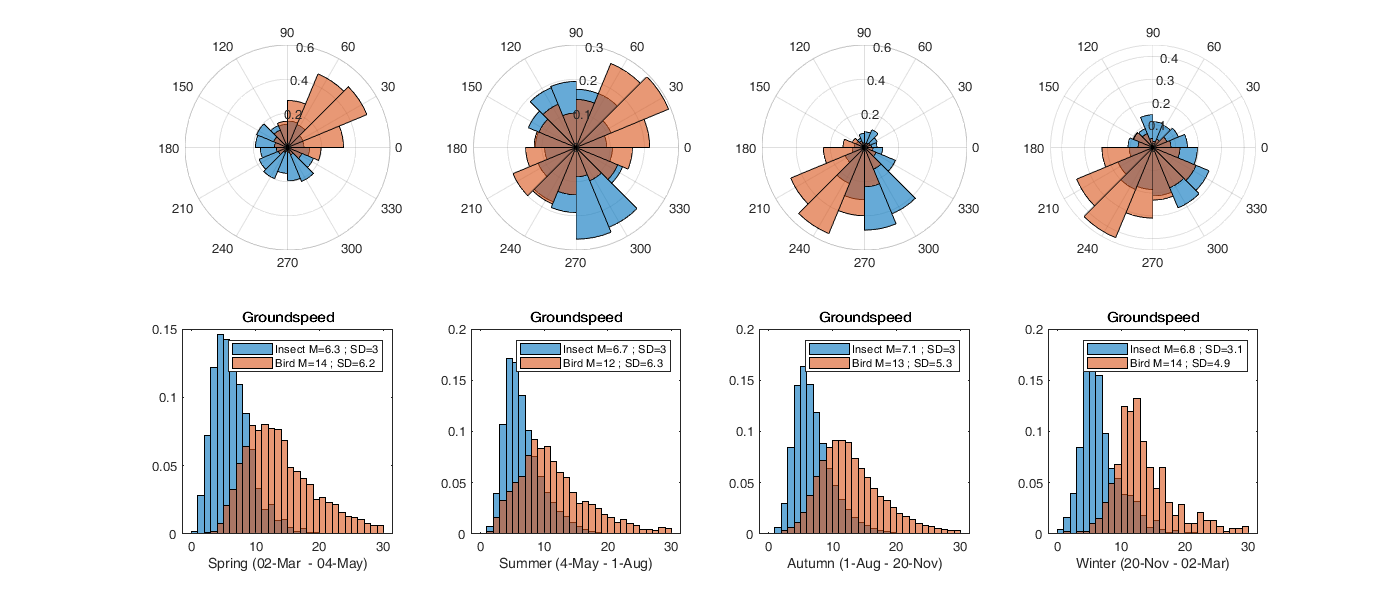

figure('position',[0 0 1400 600])
for i_s=1:4
    subplot(2,4,i_s)
    polarhistogram(angle(BSs.groundspeed(~BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm); hold on;
    polarhistogram(angle(BSs.groundspeed(BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm);
    subplot(2,4,4+i_s)
    histogram(abs(BSs.groundspeed(~BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm); hold on;
    histogram(abs(BSs.groundspeed(BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm);
    xlabel(season_label{i_s})
    legend({['Insect M=' num2str(mean(abs(BSs.groundspeed(~BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.groundspeed(~BSs.isBird & BSs.season==i_s))),2)],...
        ['Bird M=' num2str(mean(abs(BSs.groundspeed(BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.groundspeed(BSs.isBird & BSs.season==i_s))),2)]})
    title('Groundspeed');
end

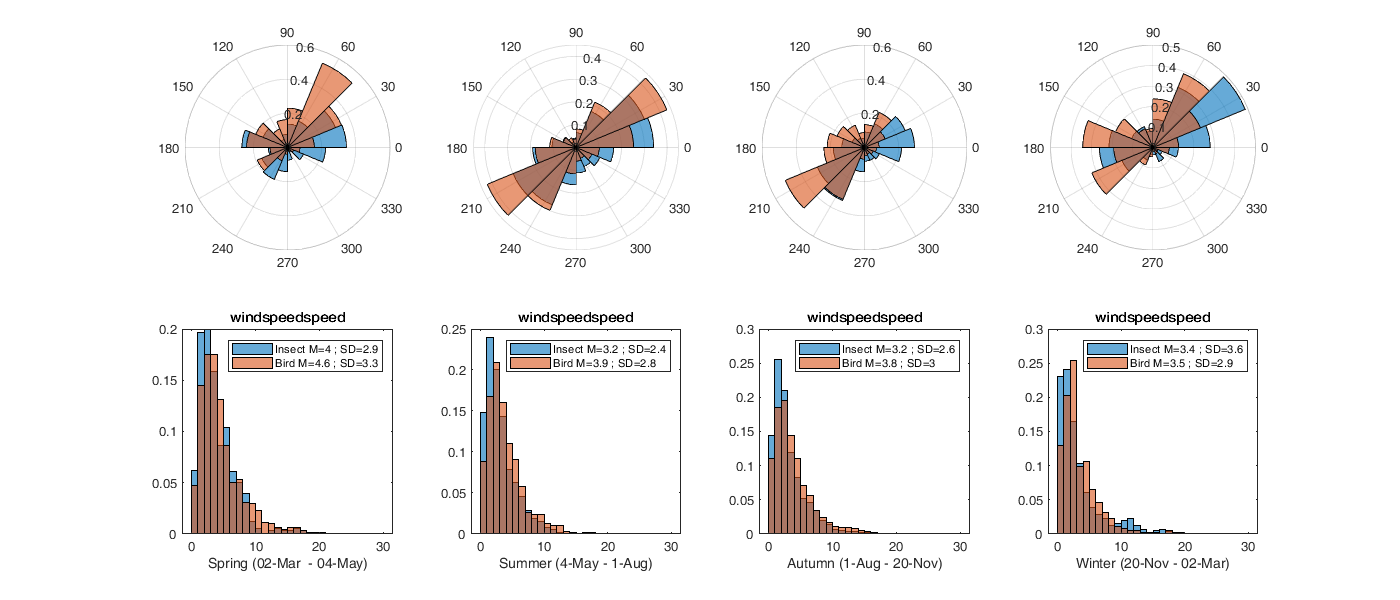

figure('position',[0 0 1400 600])
for i_s=1:4
    subplot(2,4,i_s)
    polarhistogram(angle(BSs.windspeed(~BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm); hold on;
    polarhistogram(angle(BSs.windspeed(BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm);
    subplot(2,4,4+i_s)
    histogram(abs(BSs.windspeed(~BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm); hold on;
    histogram(abs(BSs.windspeed(BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm);
    xlabel(season_label{i_s})
    legend({['Insect M=' num2str(mean(abs(BSs.windspeed(~BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.windspeed(~BSs.isBird & BSs.season==i_s))),2)],...
        ['Bird M=' num2str(mean(abs(BSs.windspeed(BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.windspeed(BSs.isBird & BSs.season==i_s))),2)]})
    title('windspeedspeed');
end

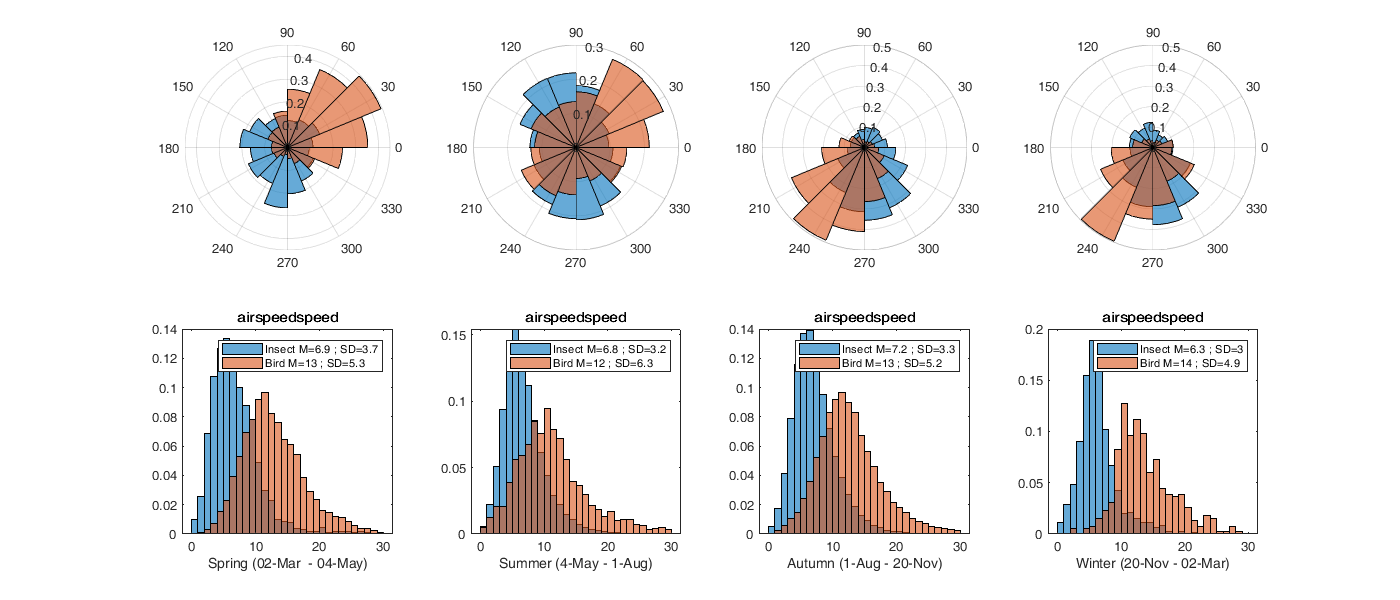

figure('position',[0 0 1400 600])
for i_s=1:4
    subplot(2,4,i_s)
    polarhistogram(angle(BSs.airspeed(~BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm); hold on;
    polarhistogram(angle(BSs.airspeed(BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm);
    subplot(2,4,4+i_s)
    histogram(abs(BSs.airspeed(~BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm); hold on;
    histogram(abs(BSs.airspeed(BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm);
    xlabel(season_label{i_s})
    legend({['Insect M=' num2str(mean(abs(BSs.airspeed(~BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.airspeed(~BSs.isBird & BSs.season==i_s))),2)],...
        ['Bird M=' num2str(mean(abs(BSs.airspeed(BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.airspeed(BSs.isBird & BSs.season==i_s))),2)]})
    title('airspeedspeed');
end

## Nighly average

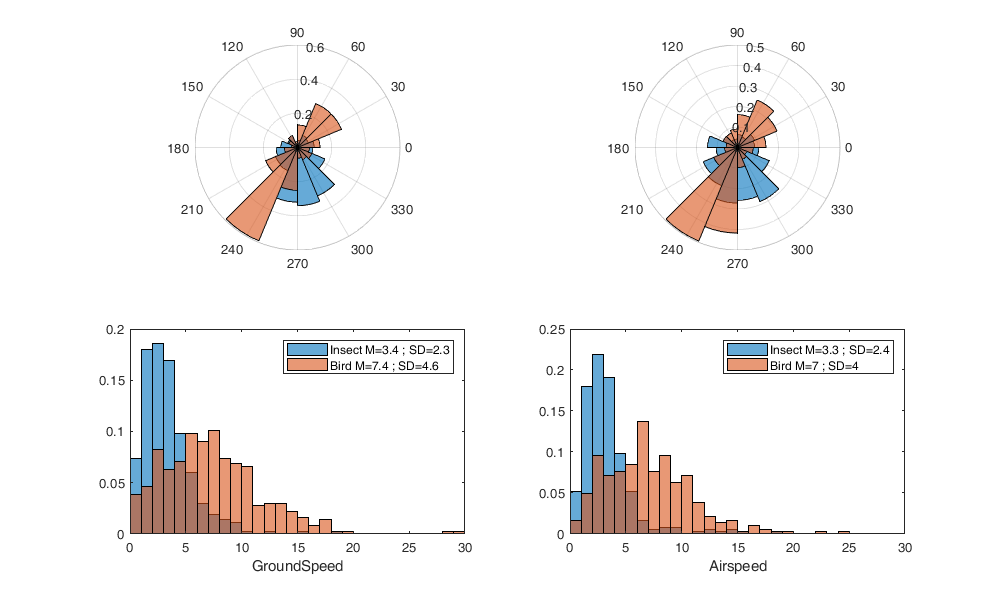

bird_groundspeed = nan(1,numel(t)); bird_airspeed = nan(1,numel(t));
insect_groundspeed = nan(1,numel(t)); insect_airspeed = nan(1,numel(t));

[G,ID] = findgroups(BSs.day_id(BSs.isBird));
bird_groundspeed(ID) = splitapply(@mean, BSs.groundspeed(BSs.isBird), G);
bird_airspeed(ID) = splitapply(@mean, BSs.airspeed(BSs.isBird), G);

[G,ID] = findgroups(BSs.day_id(~BSs.isBird));
insect_groundspeed(ID) = splitapply(@mean, BSs.groundspeed(~BSs.isBird), G);
insect_airspeed(ID) = splitapply(@mean, BSs.airspeed(~BSs.isBird), G);

figure('position',[0 0 1000 600])
subplot(2,2,1)
polarhistogram(angle(insect_groundspeed),edge_angle,'Normalization',norm); hold on;
polarhistogram(angle(bird_groundspeed),edge_angle,'Normalization',norm)
subplot(2,2,2)
polarhistogram(angle(insect_airspeed),edge_angle,'Normalization',norm); hold on;
polarhistogram(angle(bird_airspeed),edge_angle,'Normalization',norm);
subplot(2,2,3)
histogram(abs(insect_groundspeed),edge_hist,'Normalization',norm); hold on;
histogram(abs(bird_groundspeed),edge_hist,'Normalization',norm);
legend({['Insect M=' num2str(round(nanmean(abs(insect_groundspeed)),1)) ' ; SD=' num2str(round(nanstd(abs(insect_groundspeed)),1)) ],['Bird M=' num2str(round(nanmean(abs(bird_groundspeed)),1)) ' ; SD=' num2str(round(nanstd(abs(bird_groundspeed)),1)) ]})
xlabel('GroundSpeed'); xlim([0 30])
subplot(2,2,4)
histogram(abs(insect_airspeed),edge_hist,'Normalization',norm); hold on;
histogram(abs(bird_airspeed),edge_hist,'Normalization',norm);
legend({['Insect M=' num2str(round(nanmean(abs(insect_airspeed)),1)) ' ; SD=' num2str(round(nanstd(abs(insect_airspeed)),1)) ],['Bird M=' num2str(round(nanmean(abs(bird_airspeed)),1)) ' ; SD=' num2str(round(nanstd(abs(bird_airspeed)),1)) ]})
xlabel('airspeedspeed'); xlim([0 30])

## Averaging produced by WR

Roughly accounting for volume size difference with WR

Radius of weather radar (WR) and birdscan (BS). We compute the average beam width from the beam angle and the height used

rWR = 25;
hWR = (maxalt-minalt)/1000; % speed is assessed for each 200m bin. 
baBS = 17.5;% beam angle deg
rBS = @(h) h*tand(baBS);

Volume covered by WR is a cynlinder of radius `rWR` of height `hWR` (no coverage within first 5km)

VWR = rWR^2*pi*hWR-5^2*pi*hWR

VWR = 753.9822

Volume sampled by birdscan is a truncated cone of height `maxalt-minalt` and a base of `rBS` at `maxalt`.

VBS = rBS(maxalt/1000)^2*pi*maxalt/1000/3 - rBS(minalt/1000)^2*pi*minalt/1000/3

VBS = 0.0101

The duration can be found from speed.

dtBS = @(v) (VWR - VBS) / (2*rBS((maxalt+minalt)/2/1000)*v);

Assume a initial bird speed of 10 m/s -> 864 km/day

dtBS(10/1000*60*60*24)

ans = 5.3225

dtBS(20/1000*60*60*24)

ans = 2.6613

This would require to do average over 2.5-5 days. NOT POSSIBLE

Attempt to upscale the distribution

Qin=nan(3,numel(t),4); % Individual
Qan=nan(3,numel(t),4); % aggregated
nb_day=nan(numel(t),2);
for i_t=1:numel(t)
    for i_isBird=0:2
        if i_isBird==2
            tmp=BSs.groundspeed(BSs.day_id==i_t);
        else
            tmp=BSs.groundspeed(BSs.day_id==i_t & BSs.isBird==i_isBird);
        end
        
        if (size(tmp,1))>50 % minimum number of tracks to consider the night
            Qin(i_isBird+1,i_t,1)=mean(abs(tmp));
            Qin(i_isBird+1,i_t,2)=quantile(abs(tmp),.1);
            Qin(i_isBird+1,i_t,3)=quantile(abs(tmp),.9);
            Qin(i_isBird+1,i_t,4)=std(tmp);
            
            nb_day(i_t,i_isBird+1) = dtBS(mean(abs(tmp))/1000*60*60*24);
            
            [f,xi] = ksdensity([real(tmp) imag(tmp)]);
            
            xiid = datasample(1:numel(f),round(nb_day(i_t,i_isBird+1)*size(tmp,1)),'weight',f);
            
            SimSam = xi(xiid,1) + xi(xiid,2)*1i;
            Qan(i_isBird+1,i_t,1)=abs(mean(SimSam));
            Qan(i_isBird+1,i_t,2)=abs(quantile(SimSam,0.1));
            Qan(i_isBird+1,i_t,3)=abs(quantile(SimSam,0.9));
            % The radar only capture the radial velocity, on which a linear fit is performed. 
            % Radial velocity is compute here by projecting the speed vector on all possible angle of radar beam. 
            % In practice this is computed by the mean projection factor assuming a uniforme distribution of radar beam angle from 0-360 (or 0 to pi/2 as the expected value is the same from 0 to 2pi)
            % E[cos(x)]_0^{pi/2} = 2/pi
            Qan(i_isBird+1,i_t,4)=std(2/pi .* abs(SimSam)); 
        end
    end
end

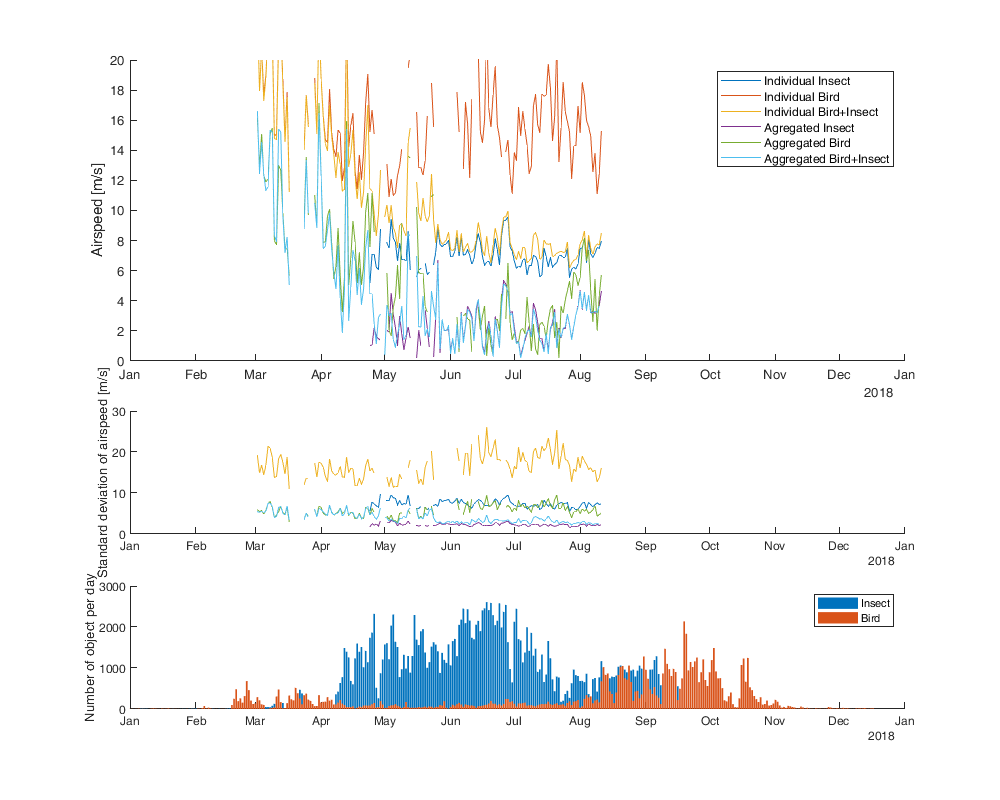

figure('position',[0 0 1000 800]); 
subplot(4,1,[1 2]);hold on;
%plot(t,Y)
%legend({'Mean of groundspeed speed over day', 'Speed of groundspeed mean over day', 'Mean of groundspeed speed for volume', 'Speed of groundspeed mean for volume'})

idt=~any(isnan(Qin(:,:,1)));
%fill([t(idt), fliplr(t(idt))], [Y(1,idt,2), fliplr(Y(1,idt,3))],'b','FaceAlpha',.2,'EdgeColor','none')
%fill([t(idt), fliplr(t(idt))], [Y(4,idt,2), fliplr(Y(4,idt,3))],'r','FaceAlpha',.2,'EdgeColor','none')
plot(t,Qin(1,:,1)); 
plot(t,Qin(2,:,1));
plot(t,Qin(3,:,1));
plot(t,Qan(1,:,1)); 
plot(t,Qan(2,:,1)); 
plot(t,Qan(3,:,1)); 
legend({'Individual Insect','Individual Bird','Individual Bird+Insect','Agregated Insect','Aggregated Bird','Aggregated Bird+Insect'})
ylim([0 20]); xlim([t(1) t(end)]); ylabel('airspeedspeed [m/s]')
subplot(4,1,3); hold on; 
plot(t,Qin(1,:,4))
plot(t,Qin(2,:,4))
plot(t,Qin(2,:,4))
plot(t,Qan(1,:,4))
plot(t,Qan(2,:,4))
plot(t,Qan(3,:,4))
% legend({'Insect','Bird'})
xlim([t(1) t(end)]);  ylabel('Standard deviation of airspeedspeed [m/s]')
subplot(4,1,4); hold on;
bar(t,histcounts(findgroups(BSs.day_id(~BSs.isBird)),0.5:1:numel(t)+0.5))
bar(t,histcounts(findgroups(BSs.day_id(BSs.isBird)),0.5:1:numel(t)+0.5))
legend({'Insect','Bird'})
xlim([t(1) t(end)]); ylabel('Number of object per day')

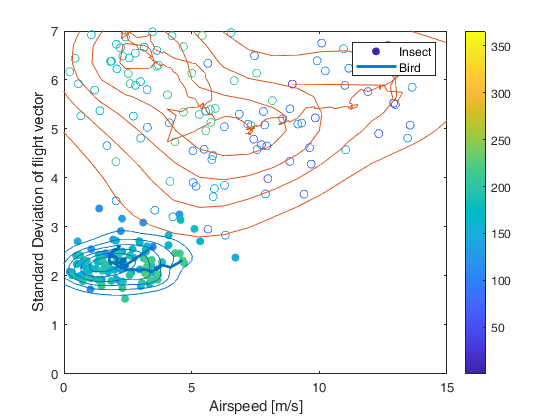

figure; hold on;
scatter(Qan(1,:,1),Qan(1,:,4),[],1:numel(t),'o','filled')
plot(movmean(Qan(1,:,1),40,'omitnan'),movmean(Qan(1,:,4),40,'omitnan'),'linewidth',2);
scatter(Qan(2,:,1),Qan(2,:,4),[],1:numel(t),'o')
plot(movmean(Qan(2,:,1),40,'omitnan'),movmean(Qan(2,:,4),40,'omitnan'))
[f,xi] = ksdensity([Qan(1,:,1)' Qan(1,:,4)']);
fb = reshape(f,sqrt(numel(f)),[]);
contour(unique(xi(:,1)),unique(xi(:,2)),fb,'Color',col(1,:))
[f,xi] = ksdensity([Qan(2,:,1)' Qan(2,:,4)']);
fi = reshape(f,sqrt(numel(f)),[]);
contour(unique(xi(:,1)),unique(xi(:,2)),fi,'Color',col(2,:));
box on; legend({'Insect','Bird'});
xlabel('airspeedspeed [m/s]'); ylabel('Standard Deviation of groundspeed vector');
axis([0 15 0 7])
colorbar()

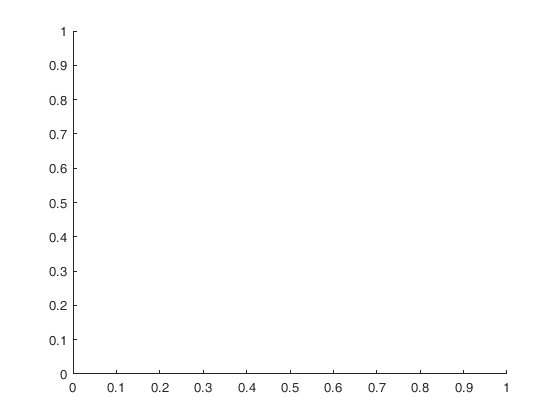

figure; hold on;

[C,h(5)]=contourf(xi1, xi2, f_1./(f_1+f_2),'ShowText','on','LineWidth',2);

Undefined function or variable 'xi1'.

scatter(Qan(3,:,1),Qan(3,:,4),[],histcounts(findgroups(BSs.day_id(BSs.isBird)),0.5:1:numel(t)+0.5)./histcounts(findgroups(BSs.day_id),0.5:1:numel(t)+0.5),'o','filled','MarkerEdgeColor','k')
%plot(movmean(Qan(1,:,1),40,'omitnan'),movmean(Qan(1,:,4),40,'omitnan'),'linewidth',2);
%scatter(Qan(2,:,1),Qan(2,:,4),[],1:numel(t),'o')
%plot(movmean(Qan(2,:,1),40,'omitnan'),movmean(Qan(2,:,4),40,'omitnan'))
% [f,xi] = ksdensity([Qan(1,:,1)' Qan(1,:,4)']);
% fb = reshape(f,sqrt(numel(f)),[]);
% contour(unique(xi(:,1)),unique(xi(:,2)),fb,'Color',col(1,:))
% [f,xi] = ksdensity([Qan(2,:,1)' Qan(2,:,4)']);
% fi = reshape(f,sqrt(numel(f)),[]);
% contour(unique(xi(:,1)),unique(xi(:,2)),fi,'Color',col(2,:));
box on; legend({'Insect','Bird'});

xlabel('airspeedspeed [m/s]'); ylabel('Standard Deviation of groundspeed vector');
axis([0 15 0 7])
colorbar()

## Comparison to WR

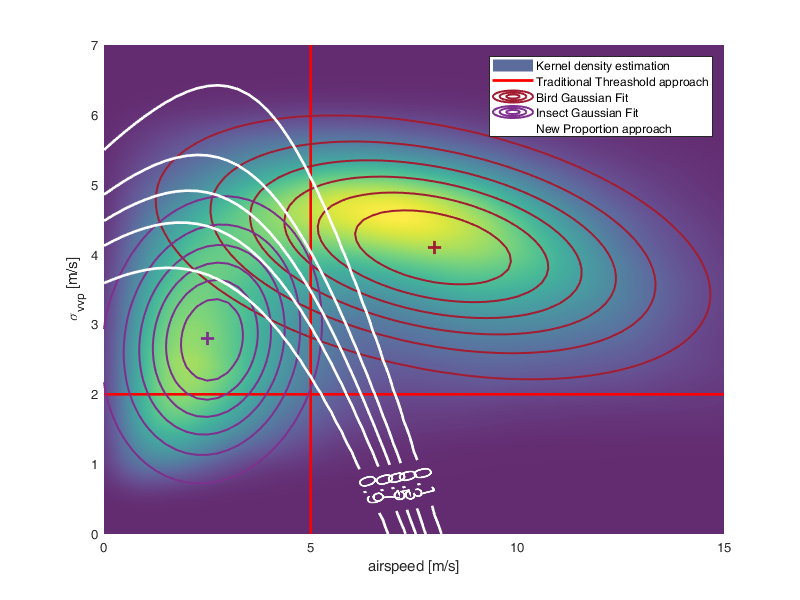

load('../data/dc_corr')
ii_d = [6 28 8];% deflg, demem, frmtc
load('../data/insect_removal')

rng('default')
gmfitBSi = fitgmdist([Qan(1,:,1)', Qan(1,:,4)'],1,'Replicates',1);

gmBSi = gmdistribution(gmfitBSi.mu, gmfitBSi.Sigma);
fBSi = reshape(pdf(gmBSi,[xi1(:) xi2(:)]),size(xi1));
fBSi = fBSi./sum(fBSi(:));

gmfitBSb = fitgmdist([Qan(2,:,1)', Qan(2,:,4)'],1,'Replicates',1);

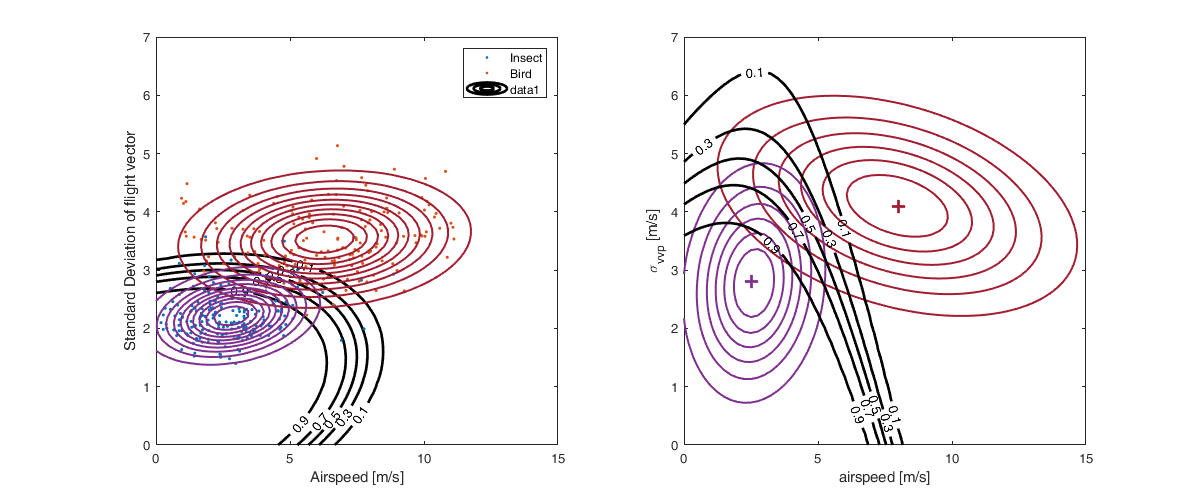

gmBSb = gmdistribution(gmfitBSb.mu, gmfitBSb.Sigma);
fBSb = reshape(pdf(gmBSb,[xi1(:) xi2(:)]),size(xi1));
fBSb = fBSb./sum(fBSb(:));

figure('position',[0 0 1200 500]); 
subplot(1,2,1); hold on;
scatter(Qan(1,:,1),Qan(1,:,4),'.')
scatter(Qan(2,:,1),Qan(2,:,4),'.')
contour3(xi1, xi2, fBSb,10,'Color',[162 29 49]/255,'linewidth',1.5);
contour3(xi1, xi2, fBSi,10,'Color',[127 47 141]/255,'linewidth',1.5);
%contour3(xi1, xi2, f_1,10,'Color',[162 29 49]/255,'linewidth',1.5);
%contour3(xi1, xi2, f_2,10,'Color',[127 47 141]/255,'linewidth',1.5);
box on; legend({'Insect','Bird'});
xlabel('airspeedspeed [m/s]'); ylabel('Standard Deviation of groundspeed vector');
axis([0 15 0 7])
[C,h(5)]=contour(xi1, xi2, fBSi./(fBSb+fBSi),.1:.2:.9,'k','ShowText','on','LineWidth',2);
%clabel(C,h(5),'FontSize',15,'Color','w','LabelSpacing',500,'FontWeight','bold')

subplot(1,2,2); hold on;
%h(1)=pcolor(xi1(1,:), xi2(:,1), ft./max(ft(:)));
% h(2)=plot([0 15],[2 2],'r','linewidth',2);
% plot([5 5],[0 7],'r','linewidth',2);
[~,h(3)]=contour(xi1, xi2, f_1,6,'Color',[162 29 49]/255,'LineWidth',1.5);
[~,id_max] = max(f_1(:)); plot(xi1(id_max),xi2(id_max),'+','Color',[162 29 49]/255,'LineWidth',2,'MarkerSize',10)
[~,h(4)]=contour(xi1, xi2, f_2,6,'Color',[127 47 141]/255,'LineWidth',1.5);
[~,id_max] = max(f_2(:)); plot(xi1(id_max),xi2(id_max),'+','Color',[127 47 141]/255,'LineWidth',2,'MarkerSize',10)
[C,h(5)]=contour(xi1, xi2, f_2./(f_1+f_2),.1:.2:.9,'k','ShowText','on','LineWidth',2);
% clabel(C,h(5),'FontSize',15,'Color','w','LabelSpacing',500,'FontWeight','bold')
% axis tight;shading interp; 
xlabel('airspeedspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');box on

%legend(h,{'Kernel density estimation','Traditional Threashold approach','Bird Gaussian Fit','Insect Gaussian Fit','New Proportion approach'})
%colormap(gca,1-(1-viridis)/1.2) %colormap(gca,viridis)

hold on
% plot(t,interp1(dc(1).time,ti(:,ii_d(1:3)),t))
Ati = mean(interp1(dc(1).time,ti(:,ii_d(1:3)),t),2);
tmp1 = Ati.*pdf(gm1,[Qan(1,:,1)' Qan(1,:,4)']);
tmp2 = (1-Ati).*pdf(gm2,[Qan(1,:,1)' Qan(1,:,4)']);
dc(i_d).bird = tmp1 ./(tmp1+tmp2);